image = imread("images/puzzle/pieces_clean.png");
gaussFactor = 2

gaussFactor = 2

smallAreaPx = 1000

smallAreaPx = 1000

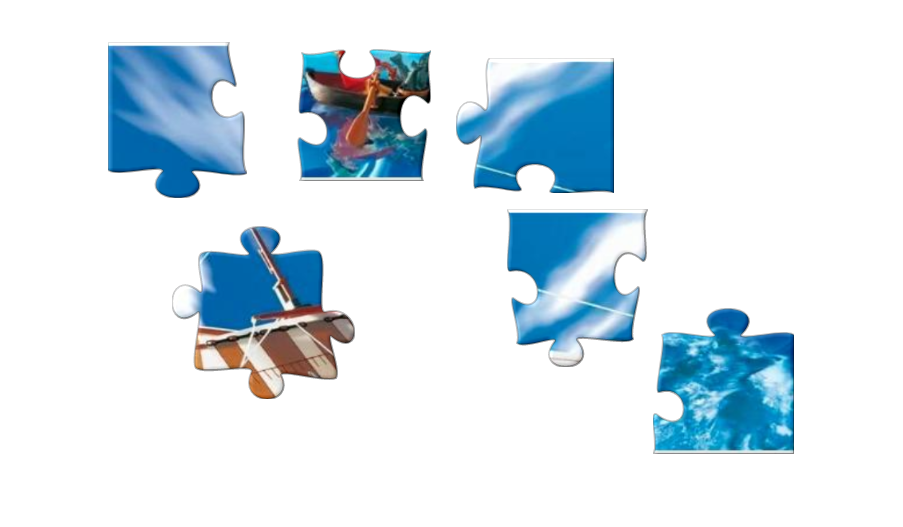


pieces = image;
imshow(pieces)

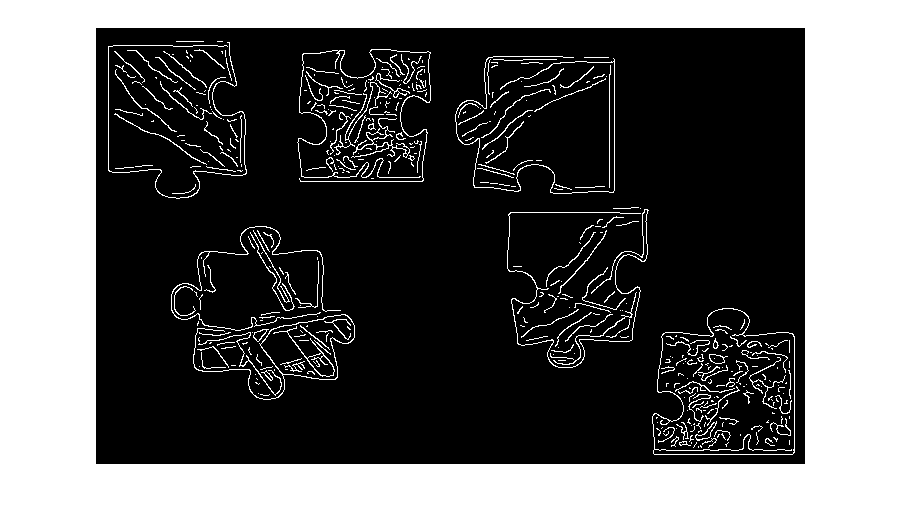

pieces = edge(rgb2gray(pieces), 'canny');
imshow(pieces, [])

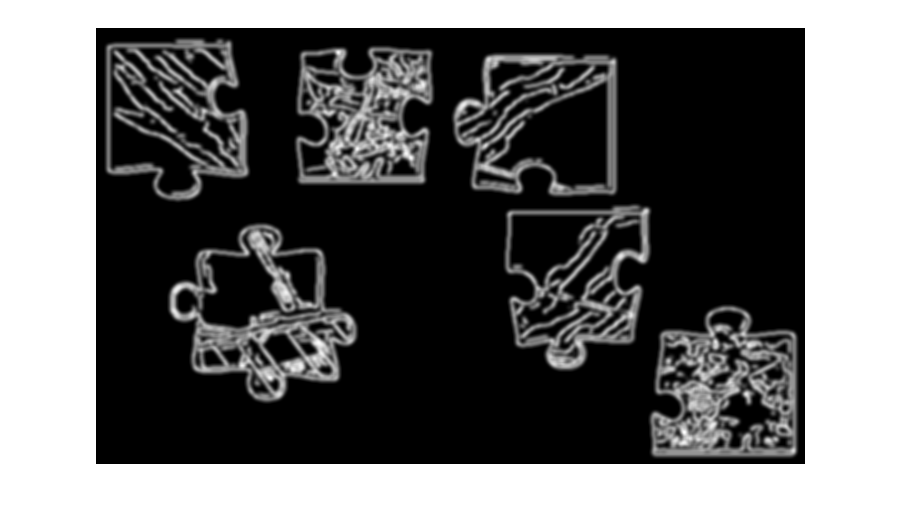

pieces = imgaussfilt(double(pieces), gaussFactor);
imshow(pieces, [])

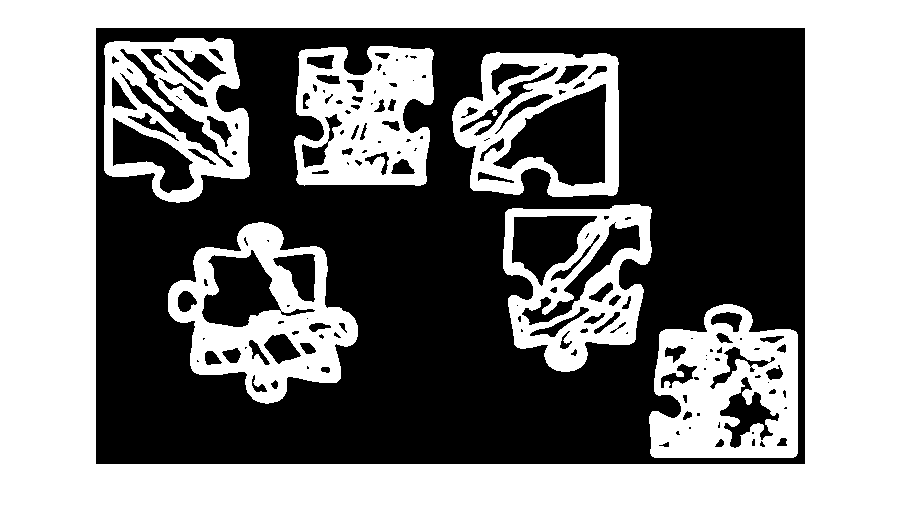

pieces = imbinarize(pieces, "adaptive", "Sensitivity", 1.0);
imshow(pieces, [])

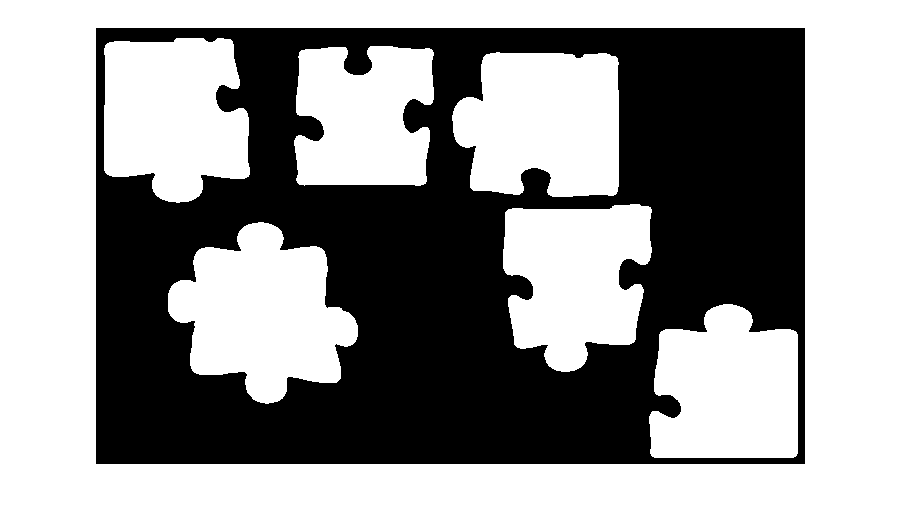

pieces = imcomplement(imfill(pieces,[1 1]) - pieces);
imshow(pieces, [])

pieces = bwareaopen(pieces, smallAreaPx);
imshow(pieces, [])

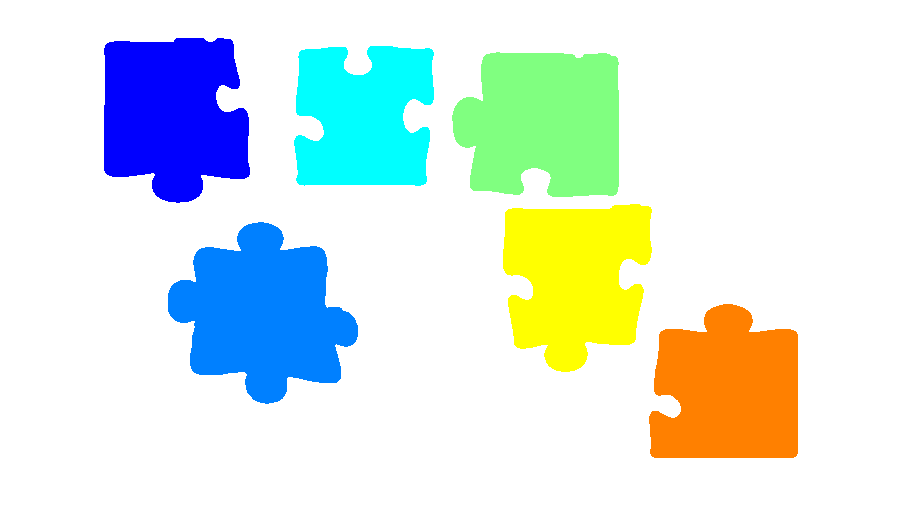

pieces = label2rgb(bwlabel(pieces));
imshow(pieces)